# Data Processing and Graph Generation for Membrane Fouling Research

### Step 1:

This chunk loads the data from 2 sources. The function load_trials pulls the data from the indivual .mat files for each experiment and compiles it into a single matlab struct. Each field in the struct is a different variable and each row represents an experiment. The second source is from the results table on the google drive. The load_results function adds additional fields to the struct for additional data.

clear
%Load Data from Trial .mat files and Results .csv files
trial = load_trials();
trial = load_results(trial);

results = 46×17 table
    TrialNumber         note           SEMs_       Salinity    ConductivityTheoretical    ConductivityStart    ConductivityEnd    StartTime     StartDate     Pressure_psi_    PumpPower    Good           Reason               Researcher        ScaleTime1_min_    ScaleTime2_min_    BatchFlowrate
    ___________    ______________    __________    ________    _______________________    _________________    _______________    __________    __________    _____________    _________    ____

### Step 2:

This chunk process the data by calculating important values and applying lowpass filters to some of the data to remove noise. 

%Process Data and Add Calculations
trial = filter_and_process(trial);

Trial #1
Trial #2
Trial #3
Trial #4
Trial #5
Trial #6
Trial #7
Trial #8
Trial #9
Trial #10
Trial #11
Trial #12
Trial #13
Trial #14
Trial #15
Trial #16
Trial #17
Trial #18
Trial #19
Trial #20
Trial #21
Trial #22
Trial #23
Trial #24
Trial #25
Trial #26
Trial #27
Trial #28
Trial #29
Trial #30
Trial #31
Trial #32
Trial #33
Trial #34


### Step 3:

Once the data is loaded and processed it can now be analyzed and plotted. All of the data lives in a matlab sturct called trial. This struct can be looked at to see summative variables like mean of batch flowrates and concentration at the membrane. 

#### Matrix Variable:

batch_flowrate_list: Raw flowrate data with units of mL/min

permeate_flowrate_list: Raw flowrate data with units of mL/min

time_list: time data from experiment in seconds

permeateFlux: Flux through membrane with units of L/m^2/hr

membraneConcentration: Concentration at Membrane with units of M

batchFlowrateFiltered: lowpassed flowrate data with units of mL/min

permeateFlowrateFiltered: lowpassed flowrate data with units of mL/min

membraneConcentrationFiltered: lowpassed concentration data with units of M

permeateFluxFiltered: lowpassed concentration data with units of L/m^2/hr

#### Numeric Values:

ConductivityStart: Conductivity at the start of the experiment with units of uS

ConductivityEnd: Conductivity at the end of the experiment with units of uS

ScaleTime1: Time it takes to scale with units of min

ScaleTime2: Time it takes to do second drop in flux with units of min

batchFlowMean: Mean batch flowrate of system with units of mL/min

batchFlowPrescaleMean: Mean batch flowrate before scaling with units of mL/min

concentration: Concentration at start of experiment with units of M

membraneConcentrationMean: Mean concentration at the membrane with units of M

membraneConcentrationPrescaleMean: Mean concentration before scaling with units of M

#### Non-numeric Values:

% %plot memb conc vs severe scaling time
% clf;
% semilogy(extractfield(trial, 'ScaleTime1'),extractfield(trial, 'membraneConcentrationPrescaleMean'),'r*')
% xlabel("Onset of severe scaling (min)")
% ylabel("CaSO4 concentration at membrane (M)")
% %title('Membrane Concentration vs. Time') %Emily note: no titles

% % %plot bulk conc vs severe scaling time
% 
% clf;
% plot(extractfield(trial, 'ScaleTime1'),extractfield(trial, 'concentration'),'k*')%Emily note: how does extractfield work? does it include non-"good" trials?
% xlabel("Onset of severe scaling (min)")
% ylabel("Bulk CaSO4 concentration (M)")

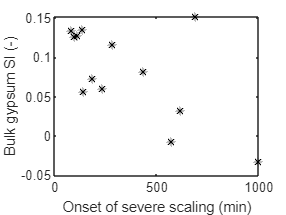

% %plot bulk SI vs severe scaling time

clf;
plot(extractfield(trial, 'ScaleTime1'),extractfield(trial, 'bulkGypsumSI'),'k*')%Emily note: how does extractfield work? does it include non-"good" trials?
xlabel("Onset of severe scaling (min)")
ylabel("Bulk gypsum SI (-)")

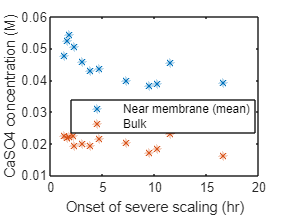

%%plot both concs vs severe scaling time
%problem: averaging initial decline over fewer hours in faster-scaling
%trials inflates mean concentration near membrane, potentially showing a
%trend where there isn't a causal relationship. To fix: Perhaps pull out
%the local minimum flux before severe scaling.
clf;
plot(extractfield(trial, 'ScaleTime1')/60, [extractfield(trial, 'membraneConcentrationPrescaleMean'); extractfield(trial, 'concentration')],'*')
xlabel("Onset of severe scaling (hr)")
ylabel("CaSO4 concentration (M)")
legend('Near membrane (mean)', 'Bulk','Location', 'best')
ylim([0.01 0.06])

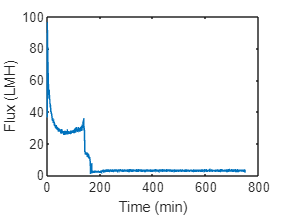

%%plot flux over time for one trial
trial_n=15;

clf;
plot(trial(trial_n).time_list(1:end-1)/60, trial(trial_n).permeateFluxFiltered)%
xlabel("Time (min)")
ylabel("Flux (LMH)")

% %%plot perm flow over time for one trial
% trial_n=15;
% 
% clf;
% plot(trial(trial_n).time_list(1:end-1)/60, trial(trial_n).permeateFlowrateFiltered)
% xlabel("Time (min)")
% ylabel("Permeate flowrate (mL/min)")

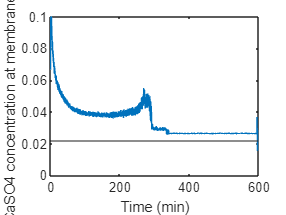

%%plot membrane conc over time for one trial
trial_n=22;

clf;
plot(trial(trial_n).time_list(1:end-1)/60, trial(trial_n).membraneConcentrationFiltered)
yline(trial(trial_n).concentration)
ylim([0 .1])
xlabel("Time (min)")
ylabel("CaSO4 concentration at membrane (M)")

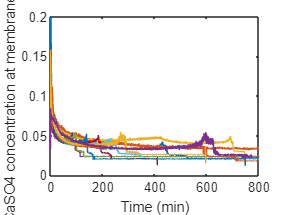

%%plot membrane conc over time for multiple trials
trial_ns=[2 3 5 7 10 11 12 14 15 16 22 24];

clf;
for i=1:length(trial_ns)
plot(trial(trial_ns(i)).time_list(1:end-1)/60, trial(trial_ns(i)).membraneConcentrationFiltered)
hold on
end
hold off
xlim([0 800])
ylim([0 .2])
xlabel("Time (min)")
ylabel("CaSO4 concentration at membrane (M)")

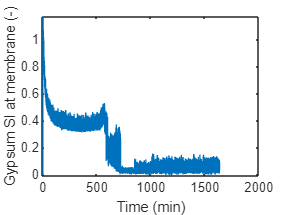

%%plot gypsum SI over time for one trial
trial_n=16;

clf;
plot(trial(trial_n).time_list(1:end-1)/60, trial(trial_n).membraneGypsumSI)
xlabel("Time (min)")
ylabel("Gypsum SI at membrane (-)")

%get average batchflow rate (TBD? "and permeate flow rate")
for i = 1:25
    trial(i).batchFlowPrescaleMean
end

ans = NaN

ans = 435.9929

ans = 489.6449

ans = NaN

ans = 507.8657

ans = 421.2315

ans = NaN

ans = NaN

ans = NaN

ans = 374.1213

ans = 390.2420

ans = 376.7523

ans = NaN

ans = 345.0093

ans = 355.6912

ans = 342.8598

ans = NaN

ans = NaN

ans = NaN

ans = NaN

ans = NaN

ans = 476.8293

ans = NaN

ans = 416.7746

ans = NaN

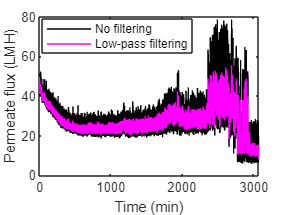

%plot filtered/unfiltered flux over time
trial_n=29;%2,11,12*,14,16
%issues: 18,20,21,

clf;
plot(trial(trial_n).time_list(5:end-1)/60, trial(trial_n).permeateFlux(5:end), 'k',trial(trial_n).time_list(5:end-1)/60, trial(trial_n).permeateFluxFiltered(5:end), 'm')

%xlim([0 300])%may cut off; may need to change
ylim([0 80])%may cut off; may need to change
xlabel("Time (min)")
ylabel("Permeate flux (LMH)")
legend('No filtering', 'Low-pass filtering','Location', 'best')

%Note: cutoff freq approx 0.04 Hz (=0.1*0.5 cycles/sample / (1.34 s/sample))